## Full System:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^{n_1} + \left(\frac{P_R}{\delta}\right)^{n_1}}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^{n_1}+ \left( \frac{P_R}{\delta} \right)^{n_1} } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^{n_2}}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^{n_2}+(\eta_AA +1)^{n_2}} $$



$$\frac{\mathrm{dy}}{\mathrm{dt}}=R_{\mathrm{growth}\;} \cdot y\left(1-y^{\upsilon } \right)$$


Parameter list:

x(1) = $\psi_g$=$\delta$

x(2) = $\psi_C$

x(3) = $P_C \cdot {\left(\eta_I \cdot I\right)}^{\frac{1}{n_2 }}$

x(4) = $\psi_d$

x(5) = $\eta_B B_{\mathrm{ext}}$

x(6) = $P_R$

x(7) = $n_1$

x(8) = $n_2$

Loading data, normalization and converting to growth rate

clear all; close all;
addpath('./MatlabFuncs/')

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

% dataTable = readtable('Data\MeanSTD_Fitting.xlsx');
dataTable = readtable('Data/MeanSTD_Fitting.xlsx'); %%mac syntax

dataTable = table2array(dataTable);
y_data = dataTable(1:4, 2:end);
y_error = dataTable(5:8, 2:end);

% Converting y to growth rate
Y0 = 1/12; K = 1; t=96; nu=3.14;
save('growthrate_fixedparam','nu','K','t','Y0','-mat');

r_data = revLogest(y_data, Y0, K, t, nu);
% disp(r_data);
r_diff = r_data(1, :) - mean(r_data(1, :));
r_norm = r_data - r_diff;
% disp(r_norm);
disp(log(2) / mean(r_data(1, :)))

   18.0904



y_norm = endLogest(r_norm, Y0, 1, t, nu);
% disp(y_norm);

Fitting the Blast and Casp9 arm together.

run('./MatlabFuncs/FuncGenerator.m');

options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',100000, 'MaxIterations',40000); 
x0_both = [0.03, 0.1, 0.5, 0.1, 1, 2, 2, 1];

lowerLim = repelem(0, length(x0_both));
upperLim = repelem(inf, length(x0_both));
[x_both, renorm_both, residual_both] = lsqcurvefit(rate_func2,x0_both,xdata,[r_norm(3, :); r_norm(2, :)],lowerLim,upperLim,options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


MSE_both = mean((residual_both).^2,2); % mean percentage error
disp(x_both);

    0.0382    0.0462    0.1818    0.0268   18.0469    6.2124    2.0006    1.2485



save('./Data/Param_Fit2', "x_both");

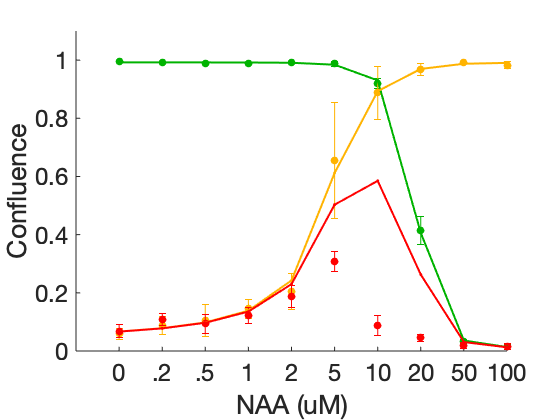

rpredict = [rate_func2(x_both, xdata); rate_comb(x_both, xdata)];
cpredict = endLogest(rpredict, Y0, 1, t, nu);

figure(1); %clf(fig);

hold on;

e1 = errorbar([1:length(xdata)],y_norm(3, :),y_error(3, :),'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
e2 = errorbar([1:length(xdata)],y_norm(2, :),y_error(2, :),'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
e3 = errorbar([1:length(xdata)],y_norm(4, :),y_error(4, :),'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);

p1 = plot([1:length(xdata)],cpredict(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);
p2 = plot([1:length(xdata)],cpredict(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);
p3 = plot([1:length(xdata)],cpredict(3,:),'.-','Color',[1, 0,0],'MarkerFaceColor',[1, 0,0],'LineWidth',2);

ylim([0, 1.1])
xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'});
xlabel('NAA (uM)');
ylabel({'Confluence'});
x1 = gca;
x1.FontSize = 24;

box off;

options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',100000, 'MaxIterations',40000); 

lowerLim = repelem(0, length(x0_both));
upperLim = repelem(inf, length(x0_both));

[x_all, renorm_all, residual_all] = lsqcurvefit(rate_func3,x0_both,xdata,[r_norm(3, :); r_norm(2, :); r_norm(4, :)],lowerLim,upperLim,options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


disp(x_all);

    0.0416    0.0590    0.1663    0.0260   16.2997    7.7079    1.5070    0.7421



save('./Data/Param_Fit3', "x_all");

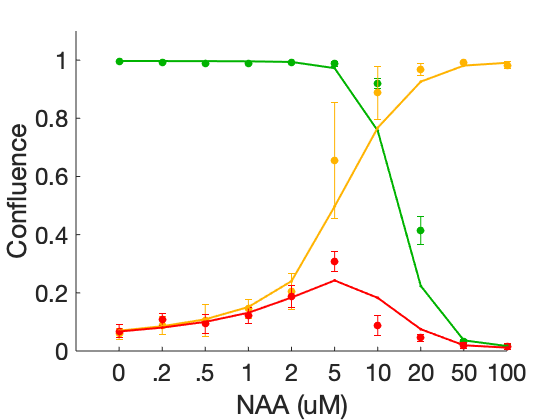

rpredict_all = rate_func3(x_all, xdata);
cpredict_all = endLogest(rpredict_all, Y0, 1, t, nu);

figure(2); %clf(fig);

hold on;

e1 = errorbar([1:length(xdata)],y_norm(3, :),y_error(3, :),'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
e2 = errorbar([1:length(xdata)],y_norm(2, :),y_error(2, :),'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
e3 = errorbar([1:length(xdata)],y_norm(4, :),y_error(4, :),'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);

p1 = plot([1:length(xdata)],cpredict_all(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);
p2 = plot([1:length(xdata)],cpredict_all(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);
p3 = plot([1:length(xdata)],cpredict_all(3,:),'.-','Color',[1, 0,0],'MarkerFaceColor',[1, 0,0],'LineWidth',2);

ylim([0, 1.1])
xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'});
xlabel('NAA (uM)');
ylabel({'Confluence'});
x2 = gca;
x2.FontSize = 24;

box off;